clear all;
clc;

global H;
global P;
global sig2;
global K;
global pos

%设置基本常量
H=150;%设置无人机飞行高度H,(m)
l0=10;%设置无人机飞行速度l0,(m/s)
P=10;%设置基站发送功率,(W)
sig2=2*1E-5;%设置噪声功率σ2 = 2×10-5,(w)
rho=3.1623;%设置门限ρ1，ρ2
max=100000;%定义搜索次数上限（实际上可能早就早于达到搜索上限之前找到了最佳点）
t=0.5;%定义单次搜索时间
left=[-l0*t,0];
right=[l0*t,0];
up=[0,l0*t];
down=[0,-l0*t];

K=3;%假设共有K个基站
gamma=0.5;%设置折扣因子γ
a0=100;%设置无人机起始横坐标
b0=100;%设置无人机起始纵坐标

%设置基础变量
x=zeros(max,2);%无人机第i次搜索之后的坐标,其中第一列为横坐标，第二列为纵坐标

pos=zeros(K,2);%基站的坐标,其中第一列为横坐标，第二列为纵坐标
pos(1,:)=[1350, 1950];
pos(2,:)=[1600, 1790];
pos(3,:)=[1590, 2090];

%生成可侦听区域半径
r_safe=sqrt(P/(rho*sig2)-H^2);%以基站为圆心的可侦听的区域的半径
theta = linspace(0,2*pi,10000);%计算可侦听区域
A(:,1) = pos(1,1)+r_safe*cos(theta);
A(:,2) = pos(1,2)+r_safe*sin(theta);
B(:,1) = pos(2,1)+r_safe*cos(theta);
B(:,2) = pos(2,2)+r_safe*sin(theta);
C(:,1) = pos(3,1)+r_safe*cos(theta);
C(:,2) = pos(3,2)+r_safe*sin(theta);
D = union(A,B,'rows');%合并所有基站的可侦听区域
D = union(C,D,'rows');

R=zeros(max,1);%第i个时刻的和信息速率评价函数

%定义第一次搜索点：

ins=left;
best=getR([a0,b0]+left);
    
if (best<getR([a0,b0]+right))
    ins=right;
    best=getR([a0,b0]+right);
end
    
if (best<getR([a0,b0]+up))
    ins=up;
    best=getR([a0,b0]+up);
end
    
if (best<getR([a0,b0]+down))
    ins=down;
    best=getR([a0,b0]+down);
end
R(1)=best;
x(1,:)=[a0,b0]+ins;

t_1st=0;%初始化第一次进入可侦听区域的时间

for i=1:1:max
    
    if(t_1st==0)%判断第一次进入可侦听区域的时间
        if(((x(i,1)-pos(1,1))^2+(x(i,2)-pos(1,2))^2<=r_safe^2)||((x(i,1)-pos(2,1))^2+(x(i,2)-pos(2,2))^2<=r_safe^2)||((x(i,1)-pos(3,1))^2+(x(i,2)-pos(3,2))^2<=r_safe^2))
            t_1st=i*t;
        end
    end
    
    if (best<getR(x(i,:)+left))
        ins=left;
        best=getR(x(i,:)+left);
    end
    
    if (best<getR(x(i,:)+right))
        ins=right;
        best=getR(x(i,:)+right);
    end
    
    if (best<getR(x(i,:)+up))
        ins=up;
        best=getR(x(i,:)+up);
    end
    
    if (best<getR(x(i,:)+down))
        ins=down;
        best=getR(x(i,:)+down);
    end
    
    if(best==R(i))
        index=i;
        break;
    end
    

    R(i+1)=best;
    x(i+1,:)=x(i,:)+ins;
end

E=0;
for i=1:1:max
    E=E+power(gamma,i-1)*R(i);
end

plot(D(:,1),D(:,2));hold on;%绘制可被侦听区域

plot(x(1:index,1),x(1:index,2));%绘制航迹图
s=scatter(pos(:,1),pos(:,2),"*");%绘制基站位置
s.LineWidth = 5;
s.MarkerEdgeColor = 'black';

disp(['第一次进入可侦听区域的时间为:',num2str(t_1st)]);

第一次进入可侦听区域的时间为:260.5



disp(['到达最佳侦听点的时刻为:',num2str(t*index)]);

到达最佳侦听点的时刻为:326


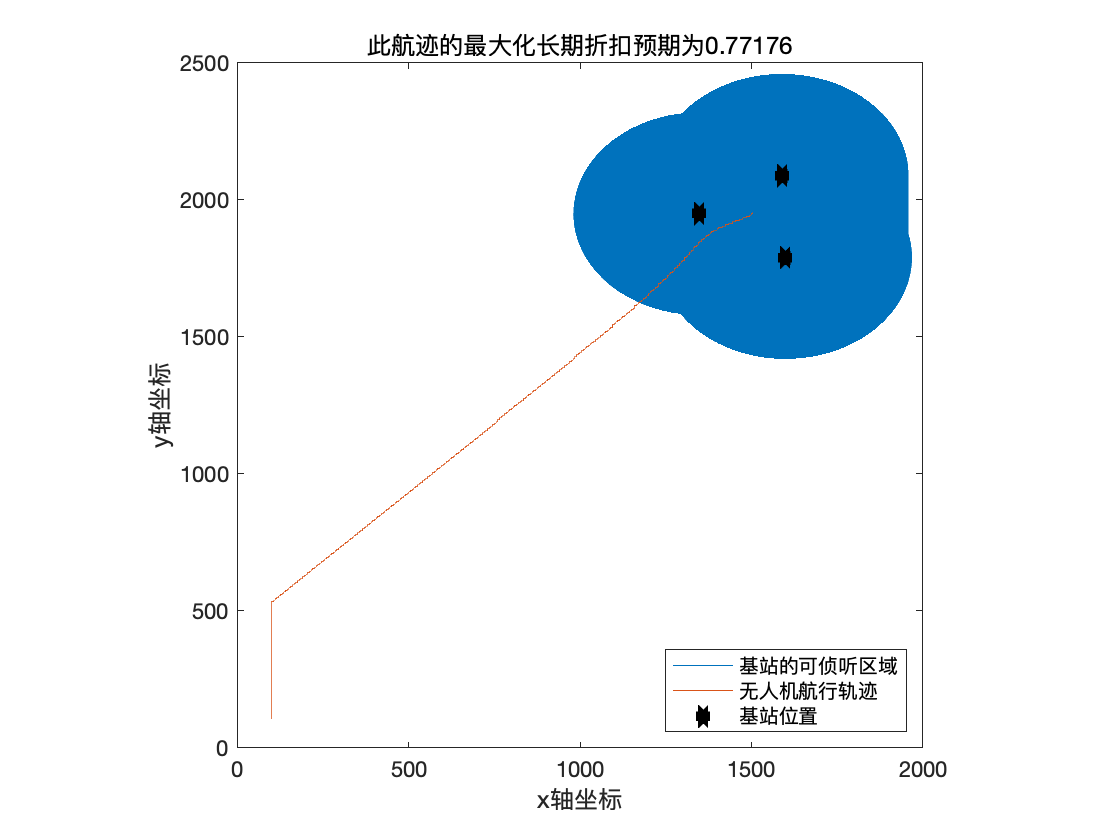



axis square;
title(['此航迹的最大化长期折扣预期为',num2str(E)]);
xlabel('x轴坐标') 
ylabel('y轴坐标') 
legend({'基站的可侦听区域','无人机航行轨迹','基站位置'},'Location','southeast')
hold off;

function Rtemp=getR(x)%得到和信息速率评价
global H;
global P;
global sig2;
global K;
global pos

d2=zeros(1,K);%无人机距离基站的距离
h=zeros(1,K);%基站与无人机之间的信道功率增益
Rk=zeros(1,K);%无人机的通信基站的信息速率评价函数分量
sum=0;

for j=1:1:K
    d2(j)=H^2+(x(1)-pos(j,1))^2+(x(2)-pos(j,2))^2;
    h(j)=1/d2(j);
    Rk(j)=log2(1+P*h(j)/sig2);
    sum=sum+Rk(j);
end

Rtemp=sum;
end
